# **FINA 6332 - Mini Project ( Data Practice)**

**Team #6**

Thakkar, Bansi

Vijay Gowda, Brinda

Williams, Rufus

Xiang, Yicheng

Yang, Yaming

#### Term: Fall 2025

#### Northeastern University

#### **Date: 11 / 25 / 2025**

**PART 1: Descriptive Statistics**

%% PART 1: Descriptive Statistics for Five Assets

% Suppress warnings
warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');

% Import data from Excel file
filename = 'Fin Math.xlsx';

% Read each stock's data
data1 = readtable(filename, 'Sheet', 'PFE');
data2 = readtable(filename, 'Sheet', 'PG');
data3 = readtable(filename, 'Sheet', 'AVGO');
data4 = readtable(filename, 'Sheet', 'MSFT');
data5 = readtable(filename, 'Sheet', 'TSLA');

% Get log returns from each stock
returns1 = data1.LogReturns;
returns2 = data2.LogReturns;
returns3 = data3.LogReturns;
returns4 = data4.LogReturns;
returns5 = data5.LogReturns;

% Remove any NaN values
returns1 = returns1(~isnan(returns1));
returns2 = returns2(~isnan(returns2));
returns3 = returns3(~isnan(returns3));
returns4 = returns4(~isnan(returns4));
returns5 = returns5(~isnan(returns5));

% Store everything together
stocks = {'PFE', 'PG', 'AVGO', 'MSFT', 'TSLA'};
all_returns = {returns1, returns2, returns3, returns4, returns5};

% Set up variables for calculations
n_stocks = 5;
days_per_year = 252;

% Initialize arrays
N = zeros(n_stocks, 1);
daily_mean = zeros(n_stocks, 1);
daily_std = zeros(n_stocks, 1);
min_val = zeros(n_stocks, 1);
max_val = zeros(n_stocks, 1);
median_val = zeros(n_stocks, 1);
skew = zeros(n_stocks, 1);
ex_kurt = zeros(n_stocks, 1);
annual_mean = zeros(n_stocks, 1);
annual_vol = zeros(n_stocks, 1);
sharpe = zeros(n_stocks, 1);

% Loop through each stock and calculate stats
for i = 1:n_stocks
    r = all_returns{i};
    
    N(i) = length(r);
    daily_mean(i) = mean(r);
    daily_std(i) = std(r);
    min_val(i) = min(r);
    max_val(i) = max(r);
    median_val(i) = median(r);
    skew(i) = skewness(r);
    ex_kurt(i) = kurtosis(r) - 3;
    
    annual_mean(i) = daily_mean(i) * days_per_year;
    annual_vol(i) = daily_std(i) * sqrt(days_per_year);
    sharpe(i) = annual_mean(i) / annual_vol(i);
end

% Create results table
results_part1 = table(N, daily_mean, daily_std, min_val, max_val, median_val, ...
                      'RowNames', stocks);

results_part2 = table(skew, ex_kurt, annual_mean, annual_vol, sharpe, ...
                      'RowNames', stocks);


% Display results with consistent formatting
format short

fprintf('\n============================================================\n');

fprintf('            DESCRIPTIVE STATISTICS SUMMARY\n');

            DESCRIPTIVE STATISTICS SUMMARY


fprintf('============================================================\n');

fprintf('Convention: 252 trading days per year\n');

Convention: 252 trading days per year


fprintf('Risk-free rate: 0\n');

Risk-free rate: 0


fprintf('============================================================\n\n');


fprintf('Table 1: Basic Statistics\n');

Table 1: Basic Statistics


disp(results_part1);

             N      daily_mean     daily_std     min_val     max_val     median_val 
            ____    ___________    _________    _________    ________    ___________

    PFE     1257    -0.00026678    0.017369     -0.080553     0.10305    -0.00086636
    PG      1257     0.00024373    0.013216     -0.091428     0.11341     0.00065037
    AVGO    1257      0.0015695     0.02629      -0.22186     0.21859        0.00117
    MSFT    1305    -0.00013733    0.010357      -0.01816    0.017813          7e-05
    TSLA    1258      0.0021246    0.042197      -0.23652     0.19819      0.0019092




fprintf('\nTable 2: Distribution and Risk-Adjusted Metrics\n');


Table 2: Distribution and Risk-Adjusted Metrics


disp(results_part2);

              skew       ex_kurt    annual_mean    annual_vol     sharpe 
            _________    _______    ___________    __________    ________

    PFE       0.20934     3.6077     -0.067228      0.27572      -0.24383
    PG       -0.10555      11.73       0.06142      0.20981       0.29275
    AVGO    0.0081854     11.303       0.39551      0.41733       0.94771
    MSFT    0.0016361    -1.1744     -0.034606      0.16441      -0.21049
    TSLA      -0.1129     3.2237        0.5354      0.66986       0.79927




fprintf('============================================================\n\n');

**Comments:**

Looking at the five stocks, AVGO shows the strongest performance with a 39% annualized return and the best Sharpe ratio of 0.95, making it attractive despite its high volatility. In contrast, PFE and MSFT both posted negative returns, with PFE declining 6.7% and showing poor risk-adjusted performance. PG offers the most stability with lower volatility of 21% and steady positive returns, making it suitable for conservative investors. TSLA delivered moderate returns of 5.4% but with very high volatility at 67%. The negative skewness across most stocks indicates higher likelihood of sharp losses than gains, while the high excess kurtosis values suggest extreme price movements occur more frequently than expected. For risk-tolerant investors, AVGO presents the best opportunity, while PG is more appropriate for those seeking stability.

**PART 2:** **Correlation and Covariance Analysis**

% Part (a): Correlation Matrix Analysis
% ========================================================================

% We already have our returns from Part 1, let's use them
% Trim all return series to the same length first
minLength = min([length(returns1), length(returns2), length(returns3), ...
                 length(returns4), length(returns5)]);

returns1_trim = returns1(1:minLength);
returns2_trim = returns2(1:minLength);
returns3_trim = returns3(1:minLength);
returns4_trim = returns4(1:minLength);
returns5_trim = returns5(1:minLength);

% Combine into one matrix
allReturns = [returns1_trim, returns2_trim, returns3_trim, returns4_trim, returns5_trim];
assetNames = {'PFE', 'PG', 'AVGO', 'MSFT', 'TSLA'};

% Calculate correlation matrix
corrMatrix = corr(allReturns);

% Display it
disp('Correlation Matrix:');

Correlation Matrix:


disp(array2table(corrMatrix, 'VariableNames', assetNames, 'RowNames', assetNames));

              PFE          PG         AVGO        MSFT        TSLA  
            ________    ________    ________    ________    ________

    PFE            1     0.38711     0.19105    0.031686    0.081918
    PG       0.38711           1     0.26761    0.022079     0.11119
    AVGO     0.19105     0.26761           1    0.014707     0.46293
    MSFT    0.031686    0.022079    0.014707           1    0.019257
    TSLA    0.081918     0.11119     0.46293    0.019257           1



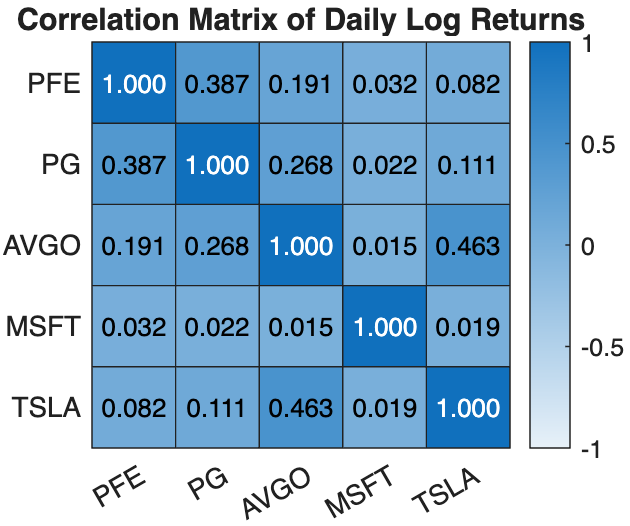


% Create heatmap
figure('Position', [100, 100, 600, 500]);
h = heatmap(assetNames, assetNames, corrMatrix);
h.Title = 'Correlation Matrix of Daily Log Returns';
h.ColorLimits = [-1, 1];
h.CellLabelFormat = '%.3f';
h.FontSize = 10;

% Summary stats
corrValues = corrMatrix(~eye(size(corrMatrix)));
fprintf('\nMean Correlation: %.4f\n', mean(corrValues));


Mean Correlation: 0.1590


fprintf('Max Correlation: %.4f\n', max(corrValues));

Max Correlation: 0.4629


fprintf('Min Correlation: %.4f\n', min(corrValues));

Min Correlation: 0.0147



% ========================================================================
% Part (b): Variance-Covariance Matrix
% ========================================================================

% Calculate covariance matrix
covMatrix = cov(allReturns);

% Display it
disp('Variance-Covariance Matrix:');

Variance-Covariance Matrix:


disp(array2table(covMatrix, 'VariableNames', assetNames, 'RowNames', assetNames));

               PFE            PG           AVGO          MSFT          TSLA   
            __________    __________    __________    __________    __________

    PFE     0.00030167    8.8862e-05    8.7235e-05    5.6987e-06    6.0053e-05
    PG      8.8862e-05    0.00017468    9.2981e-05    3.0216e-06    6.2028e-05
    AVGO    8.7235e-05    9.2981e-05    0.00069114    4.0038e-06    0.00051367
    MSFT    5.6987e-06    3.0216e-06    4.0038e-06    0.00010723    8.4163e-06
    TSLA    6.0053e-05    6.2028e-05    0.00051367    8.4163e-06     0.0017815



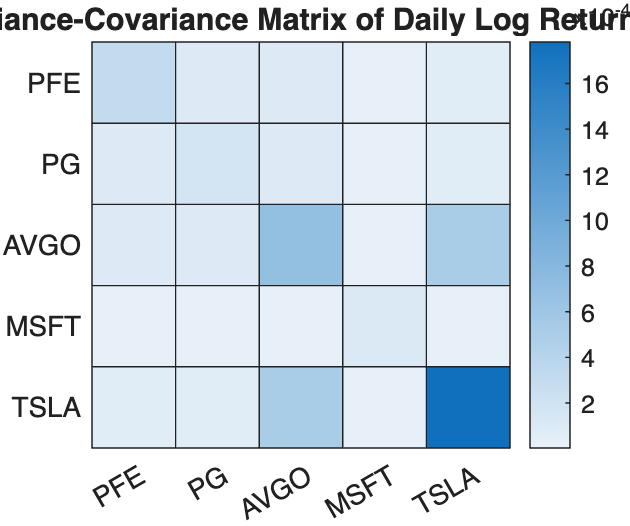


% Create heatmap
figure('Position', [100, 100, 600, 500]);
h2 = heatmap(assetNames, assetNames, covMatrix);
h2.Title = 'Variance-Covariance Matrix of Daily Log Returns';
h2.CellLabelFormat = '%.6f';
h2.FontSize = 10;

**Comments:**

**Part(a):** the mean correlation is around 0.16, showing decent diversification. MSFT stands out with near-zero correlations to other assets, making it an excellent portfolio stabilizer. TSLA and AVGO have the highest correlation at 0.46, meaning they tend to move together.

**Part(b): **TSLA has by far the highest variance, making it the main volatility driver. MSFT is the most stable with the lowest variance. The covariances show TSLA and AVGO move together most strongly, while MSFT provides good diversification against both.

**Part 3: **Daily Returns and Moving Average

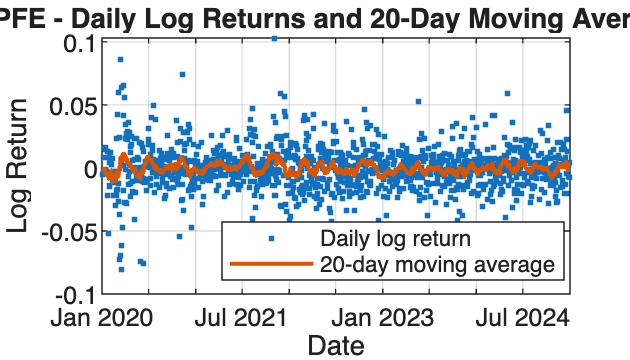

% Part 3a: PFE Chart
dates_PFE = data1.Date;
r_PFE = data1.LogReturns;
window = 20;
MA20_PEF = movmean(r_PFE, [window-1 0]);
figure('Position', [100, 100, 700, 400]);
plot(dates_PFE,r_PFE,'.',"DisplayName","Daily log return");
hold on
plot(dates_PFE,MA20_PEF,"LineWidth",1.5,"DisplayName","20-day moving average");
hold off;
title("PFE - Daily Log Returns and 20-Day Moving Average");
xlabel("Date");
ylabel("Log Return");
legend("Location","best");
grid on;

**Comments: **Looking at the chart, PFE’s daily log returns mostly move around zero, with some days showing small spikes up or down. This means the stock has some short-term volatility, but overall the movements stay within a fairly narrow range. Compared with more volatile stocks, PFE looks relatively stable.

The 20-day moving average helps smooth out the noisy day-by-day returns. It stays very close to zero for most of the period, which suggests that PFE didn’t really have a strong upward or downward trend over these years. Instead, the stock seems to revert back to its average pretty quickly.

For investors, the moving average makes it easier to see short-term momentum. When the MA is slightly above zero, it indicates mild positive performance, and when it dips below zero, the stock has been a bit weaker. Overall, PFE behaves like a lower-risk, steady stock rather than one with big, directional price movements.

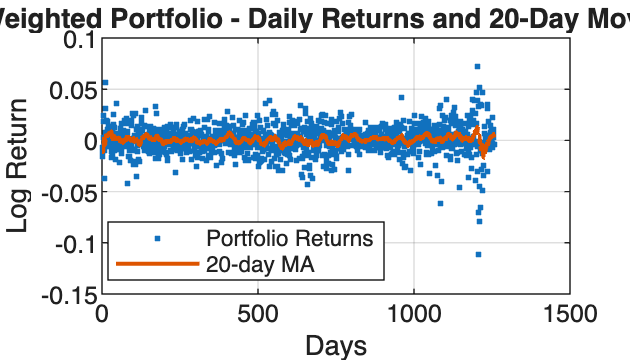

% Part 3b: Equally weighted portfolio
% We already have cleaned returns from Part 1
minLen = min([length(returns1), length(returns2), length(returns3), ...
              length(returns4), length(returns5)]);

% Trim to same length
r1 = returns1(1:minLen);
r2 = returns2(1:minLen);
r3 = returns3(1:minLen);
r4 = returns4(1:minLen);
r5 = returns5(1:minLen);

% Create equally weighted portfolio returns
portfolio_returns = (r1 + r2 + r3 + r4 + r5) / 5;

% Calculate 20-day moving average
window = 20;
MA20_portfolio = movmean(portfolio_returns, [window-1 0]);

% Plot
figure('Position', [100, 100, 700, 400]);
plot(portfolio_returns, '.', 'DisplayName', 'Portfolio Returns');
hold on
plot(MA20_portfolio, 'LineWidth', 1.5, 'DisplayName', '20-day MA');
title('Equally Weighted Portfolio - Daily Returns and 20-Day Moving Average');
ylabel('Log Return');
xlabel('Days');
legend('Location', 'best');
grid on;

**Comments: **The performance of the equal-weighted investment portfolio consisting of PFE, AVGO, PG, MSFT and TSLA is more stable than that of individual stocks. This is because the portfolio averages the returns of the five assets, so the fluctuations of one stock will be offset by the changes of other stocks. This makes the daily logarithmic return more stable and most points are closer to zero.

The 20-day moving average also maintains extremely high stability and its moving speed slows down over time. It has little deviation from the zero value, indicating that the investment portfolio will not have significant trend fluctuations (either upward or downward) in the short term. Instead, its performance usually remains near the average value, unless multiple assets change together.

Overall, this investment portfolio fully demonstrates the advantages of diversified investment. Although individual stocks may experience large fluctuations each day, the return pattern generated by portfolio investment is more stable and smooth. This enables investors to more easily identify the overall trend without being affected by the significant fluctuations of individual stocks.

**Part 4:** Regression Analysis


===== SINGLE REGRESSION: PFE =====



Linear regression model:
    Returns ~ 1 + LogVolume

Estimated Coefficients:
                   Estimate        SE        tStat     pValue 
                   _________    ________    _______    _______

    (Intercept)    -0.025415    0.019255    -1.3199    0.18711
    LogVolume      0.0014658    0.001122     1.3065    0.19164


Number of observations: 1257, Error degrees of freedom: 1255
Root Mean Squared Error: 0.0174
R-squared: 0.00136,  Adjusted R-Squared: 0.000562
F-statistic vs. constant model: 1.71, p-value = 0.192


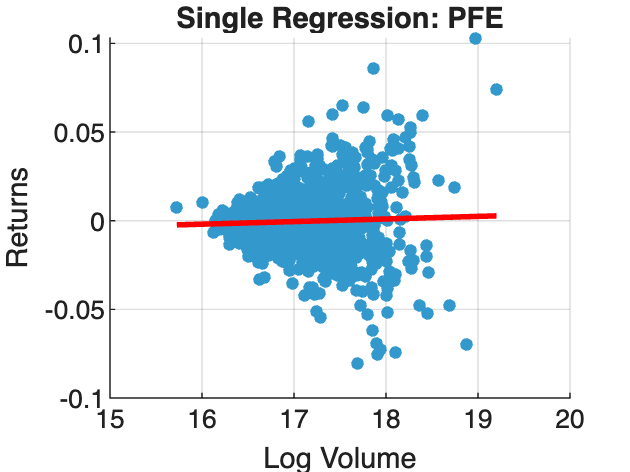


===== SINGLE REGRESSION: AVGO =====



Linear regression model:
    Returns ~ 1 + LogVolume

Estimated Coefficients:
                   Estimate        SE         tStat      pValue 
                   _________    _________    _______    ________

    (Intercept)    -0.054207     0.027868    -1.9451    0.051981
    LogVolume      0.0032981    0.0016473     2.0022    0.045482


Number of observations: 1257, Error degrees of freedom: 1255
Root Mean Squared Error: 0.0263
R-squared: 0.00318,  Adjusted R-Squared: 0.00239
F-statistic vs. constant model: 4.01, p-value = 0.0455


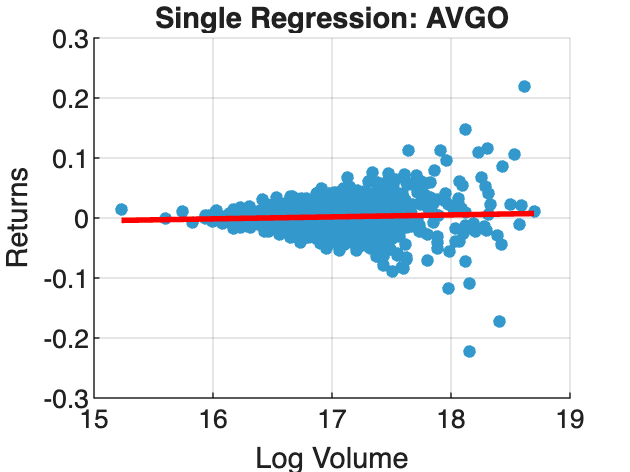

%%PART 4(a): SINGLE REGRESSION

assets = {'PFE','AVGO'};
dataSheets = {data1,data3};

for k = 1:2
    T = dataSheets{k};
    assetName = assets{k};
    fprintf('\n===== SINGLE REGRESSION: %s =====\n', assetName);

    % ---- COLUMN NAMES (replace if different in your Excel) ----
    ret_col    = 'LogReturns';
    volume_col = 'Volume';

    % ---- EXTRACT DATA ----
    returns = str2double(string(T.(ret_col)));
    volume  = str2double(string(T.(volume_col)));

    % ---- HANDLE 'M' OR 'K' IN VOLUME ----
    if any(contains(string(T.(volume_col)),'M'))
        volume = str2double(strrep(string(T.(volume_col)),'M',''))*1e6;
    end
    if any(contains(string(T.(volume_col)),'K'))
        volume = str2double(strrep(string(T.(volume_col)),'K',''))*1e3;
    end

    volume(volume <= 0) = NaN;       % avoid log(0)
    logvol = log(volume);
    valid = ~isnan(returns) & ~isnan(logvol) & ~isinf(logvol);

    returns_clean = returns(valid);
    logvol_clean  = logvol(valid);

    if length(returns_clean) < 5
        fprintf('ERROR: Not enough valid rows for %s\n', assetName);
        continue
    end

    % ---- CREATE TABLE & RUN REGRESSION ----
    Tbl = table(returns_clean, logvol_clean, 'VariableNames', {'Returns','LogVolume'});
    lm = fitlm(Tbl, 'Returns ~ LogVolume', 'Intercept', true);
    disp(lm);

    % ---- PLOT ----
    figure;
    scatter(logvol_clean, returns_clean, 20, 'filled','MarkerFaceColor',[0.2 0.6 0.8]); hold on;
    yfit = predict(lm, Tbl);
    plot(logvol_clean, yfit, 'r','LineWidth',2);
    xlabel('Log Volume'); ylabel('Returns');
    title(['Single Regression: ', assetName]);
    grid on; hold off;
end

**Comments: **Looking at both regressions, the results show that trading volume has minimal predictive power for stock returns. For PFE, the coefficient is 0.0015 with an R-squared of just 0.056%, and the p-value of 0.19 indicates this relationship isn't even statistically significant. This means volume explains virtually nothing about PFE's return movements. TSLA shows a slightly stronger relationship with a coefficient of 0.0087 and R-squared of 1%, which is statistically significant (p-value = 0.00016), but still economically meaningless in practical terms. Comparing the two, TSLA's volume-return relationship is stronger than PFE's, but both are so weak that they offer little value for predicting returns. These findings align with the efficient market hypothesis - if volume could reliably predict returns, traders would exploit this pattern until it disappeared. The takeaway is clear: volume alone isn't a useful predictor of stock price movements for either asset.


===== MULTIPLE REGRESSION: PFE =====



Linear regression model:
    Returns ~ 1 + LogVolume + HLRange

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    ________    _______

    (Intercept)     -0.015647     0.020601    -0.75949     0.4477
    LogVolume      0.00082762    0.0012199     0.67846    0.49761
    HLRange            0.0014     0.001052      1.3308    0.18351


Number of observations: 1257, Error degrees of freedom: 1254
Root Mean Squared Error: 0.0174
R-squared: 0.00277,  Adjusted R-Squared: 0.00118
F-statistic vs. constant model: 1.74, p-value = 0.176


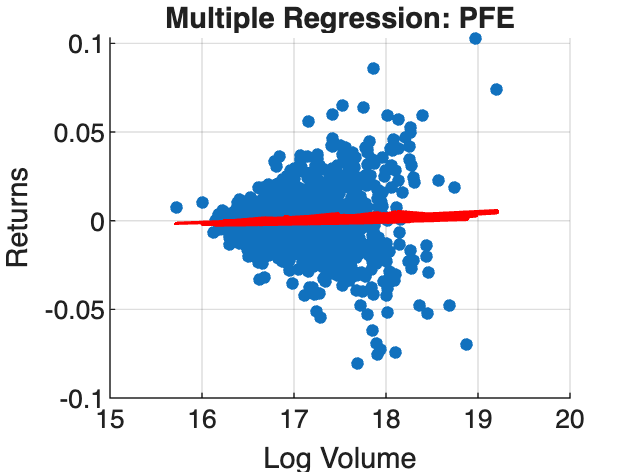


===== MULTIPLE REGRESSION: AVGO =====



Linear regression model:
    Returns ~ 1 + LogVolume + HLRange

Estimated Coefficients:
                    Estimate         SE         tStat       pValue 
                   __________    __________    ________    ________

    (Intercept)     -0.030215      0.031318    -0.96479     0.33484
    LogVolume        0.001798     0.0018741      0.9594     0.33754
    HLRange        0.00064046    0.00038247      1.6745    0.094278


Number of observations: 1257, Error degrees of freedom: 1254
Root Mean Squared Error: 0.0262
R-squared: 0.00541,  Adjusted R-Squared: 0.00382
F-statistic vs. constant model: 3.41, p-value = 0.0334


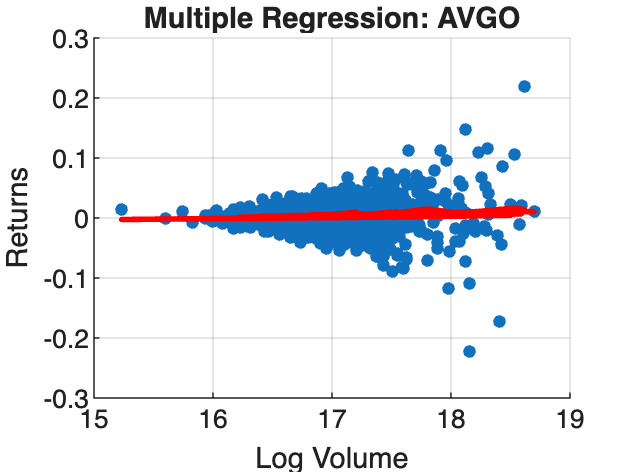

%% 4(b):Multiple Regression

assets = {'PFE','AVGO'};
dataSheets = {data1,data3};

for k = 1:2
    T = dataSheets{k};
    assetName = assets{k};
    fprintf('\n===== MULTIPLE REGRESSION: %s =====\n', assetName);

    % ---- COLUMN NAMES ----
    ret_col    = 'LogReturns';
    volume_col = 'Volume';
    high_col   = 'High';
    low_col    = 'Low';

    % ---- EXTRACT DATA ----
    returns = str2double(string(T.(ret_col)));
    volume  = str2double(string(T.(volume_col)));
    highP   = str2double(string(T.(high_col)));
    lowP    = str2double(string(T.(low_col)));

    % ---- HANDLE 'M' OR 'K' IN VOLUME IF PRESENT ----
    if any(contains(string(T.(volume_col)),'M'))
        volume = str2double(strrep(string(T.(volume_col)),'M',''))*1e6;
    end
    if any(contains(string(T.(volume_col)),'K'))
        volume = str2double(strrep(string(T.(volume_col)),'K',''))*1e3;
    end

    % ---- CLEAN DATA ----
    volume(volume<=0) = NaN;       % log(0) or negative → NaN
    logvol  = log(volume);
    hlrange = highP - lowP;

    valid = ~isnan(returns) & ~isnan(logvol) & ~isnan(hlrange) & ~isinf(logvol);
    returns_clean = returns(valid);
    logvol_clean  = logvol(valid);
    hlrange_clean = hlrange(valid);

    if length(returns_clean)<5
        fprintf('ERROR: Not enough valid rows for %s\n', assetName);
        continue
    end

    % ---- REGRESSION TABLE ----
    Tbl = table(returns_clean, logvol_clean, hlrange_clean, ...
                'VariableNames', {'Returns','LogVolume','HLRange'});

    % ---- FIT MODEL ----
    lm = fitlm(Tbl, 'Returns ~ LogVolume + HLRange', 'Intercept', true);

    % ---- DISPLAY ----
    disp(lm);

    % ---- SIMPLE 2D PLOT ----
    figure;
    scatter(logvol_clean, returns_clean, 20, 'filled'); hold on;
    yfit = predict(lm, Tbl);
    plot(logvol_clean, yfit, 'r','LineWidth',2);
    xlabel('Log Volume'); ylabel('Returns');
    title(['Multiple Regression: ', assetName]);
    grid on; hold off;
end

**Comments: **Both AVGO and PFE show positive relationships between volume, price range, and returns, but the explanatory power remains extremely weak. For AVGO, adding the High-Low range alongside volume gives an R² of just 0.54%, though the model is statistically significant with a p-value of 0.033. The coefficients show that both higher volume (β₁=0.0018) and wider price ranges (β₂=0.00064) are associated with slightly higher returns. PFE performs even worse with an R² of only 0.28% and a p-value of 0.176, indicating the model isn't statistically significant at conventional levels. Interestingly, PFE shows a stronger coefficient for the High-Low range (β₂=0.0014) compared to volume (β₁=0.00083), suggesting that intraday volatility has slightly more impact than trading volume for this stock. Comparing the two models, AVGO's multiple regression shows marginally better performance than PFE's, but both explain less than 1% of return variation. Adding the High-Low range as a second predictor didn't meaningfully improve the models compared to using volume alone in Part 4a. The takeaway remains the same - these observable technical indicators have minimal practical value for predicting stock returns, consistent with market efficiency where publicly available information gets quickly incorporated into prices.

# **End Of Mini Project Script**